## **7. gyakorlat**

#### **1. Feladat**

Közelítsük az $f(y)=y^3-y$ függvényt a $[0,2]$ intervallumon másodfokú polinommal. Hogyan kell választanunk az alappontokat, hogy az intervallumon vett hiba minimális legyen? Mik lesznek az alappontok és mennyi a minimális hiba?

k=[0,1,2];
x=cos((2*k+1)/6*pi)+1

x =     1.8660    1.0000    0.1340


f=@(x) x.^3-x;
y=f(x)

y =     4.6316         0   -0.1316



p=polyfit(x,y,2);
xx=linspace(0,2,100);
pp=polyval(p,xx);
ff=f(xx);

hh=ff-pp;
hiba=max(abs(hh));
disp(hiba)

    0.2500



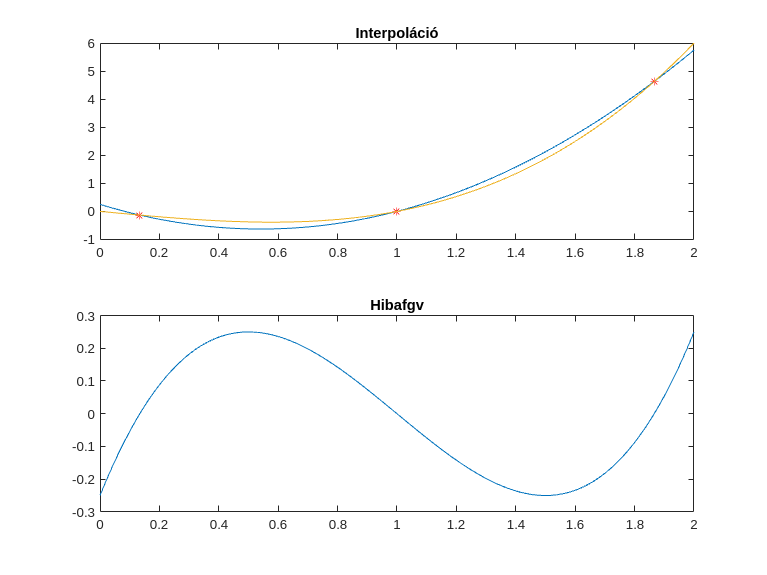


subplot(2,1,1)
plot(xx,pp,x,y,'r*',xx,ff)
title("Interpoláció")

subplot(2,1,2)
plot(xx,hh)
title("Hibafgv")

subplot

#### 2. Feladat

Írjunk olyan függvényt, mely osztott differencia táblázatot készít!

Bemenő paraméterek:

- `x:` az alappontok vektora`, `

- `y:`a függvényértékek vektora.

Kimenő paraméter:

- `C: `mátrix, mely alsó háromszög részében a kiszámított osztott differenciákat tartalmazza.

% Megoldás
x=[1,4,9];
y=[1,2,3];

C=osztottdiff(x,y);
C

C =     1.0000         0         0
    2.0000    0.3333         0
    3.0000    0.2000   -0.0167


#### **3. Feladat**

Írjunk olyan függvényt, mely az osztott differencia táblázatból és az alappontokból egy vektor elemein kiértékeli a Newton-alakot!

Bemenő paraméterek: 

- `C: `mátrix, mely alsó háromszög részében a kiszámított osztott differenciákat tartalmazza, 

- `x:` az alappontok vektora`, `

- `xx:` a kiértékelendő pontok vektora.

Kimenő paraméter: 

- `yy: `az `xx`-hez tartozó értékek vektora.

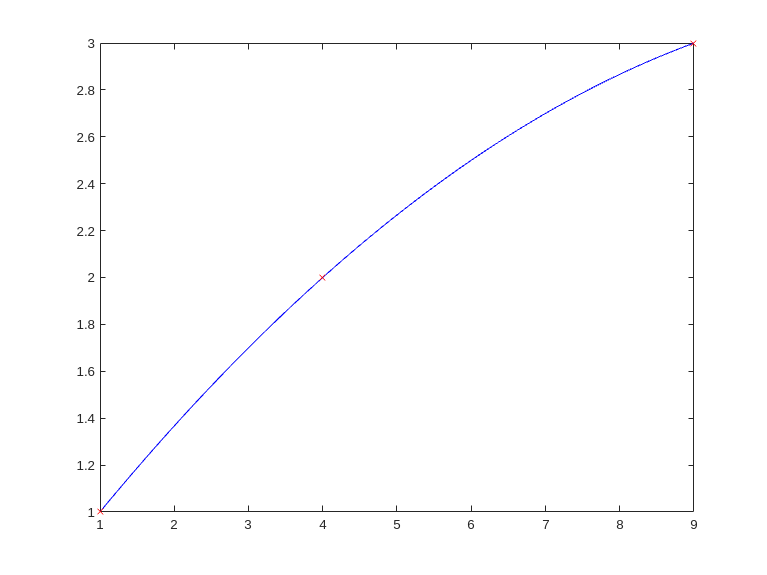

% Megoldás

xx=linspace(1,9,100);

yy=interp_newton(C,x,xx);
plot(xx,yy,'b-');
hold on
plot(x,y,'rx')
hold off

#### **4. Feladat:    **

Legyen $f(x)=x\sin\left(\frac{\pi}{x}\right) ~ (x \in [0,1])$, az alappontok pedig $x_k^{(n)}:=\frac{1}{k+1} ~(k=0,\dots,n-1)$. Mivel $f(x_k^{(n)})=0$, az interpolációs polinom az azonosan 0 polinom. Ekkor az interpolációs polinomok sorozata egyenletesen konvergens, de nem $f(x)$-hez, hanem $0$-hoz konvergál! Készítsük el a fenti interpolációs feladatot demonstráló programot, rajzoljuk ki $f$-et és az interpolációs polinomot különböző $n$-ek esetén!

% Megoldás


#### **5. Feladat:**

Legyen $f(x)=|x| ~(x \in [-1,1])$. Írjunk két programot a függvény $n$-ed fokú interpolációs polinommal történő közelítésére két különböző alappontrendszeren. Ábrázoljuk a függvényt és a polinomot is egy koordinátarendszerben és vizsgáljuk a hibát 

- ekvidisztans (egyenletes felosztású) alappontrendszeren;

- majd a Csebisev-polinom gyökeit véve alappontoknak!

Az alappontok számának növelésekor mit tapasztalunk a két különböző esetben?

% Megoldás

n=10;
f=@(x) abs(x);

interp_ekvidisztans(n,f);
interp_csebisev(n,f);

#### **6. Feladat:**

Ismételjük meg az előző feladatot $f(x)=\frac{1}{1+25x^2} ~(x\in[-1,1])$ Runge példájára! Módosítsuk a programot úgy, hogy képes legyen paraméterként átvenni az $f$ függvényt!

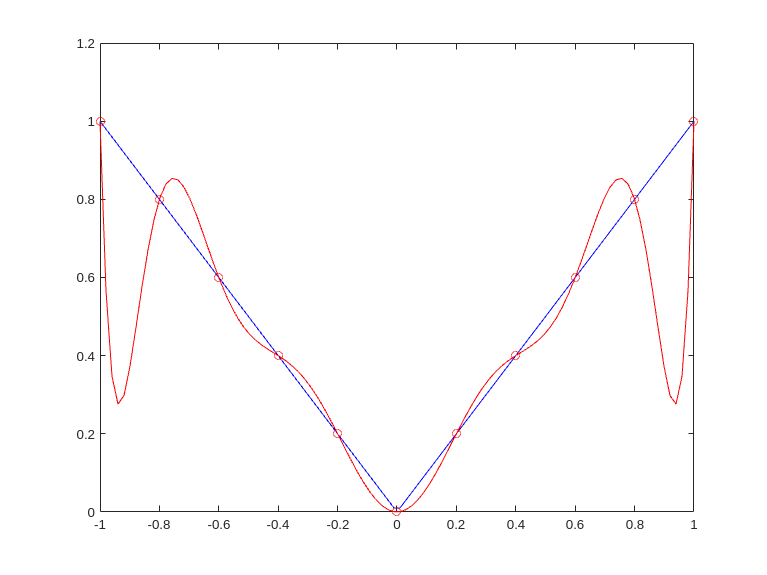

% Megoldás

n=20;
f=@(x) 1./(1+25*x.^2)

interp_ekvidisztans(n,f);

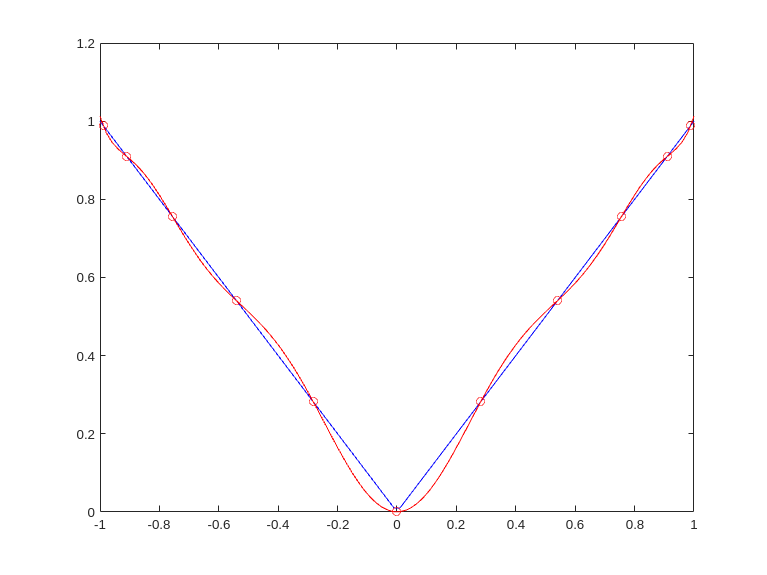

interp_csebisev(n,f);

#### **7. Feladat**

Készítsünk programot, mely összehasonlítja $[-1,1]$-en az egyenletes felosztásra illetve a Csebisev-gyökökre épülő polinomot. Számítsuk ki (közelítsük) a végtelen normát mindkét esetben, és rajzoltassuk ki mindkét polinomot!

Bemenő paraméter: 

- `n: `az interpolációs polinom fokszáma.

- `f:` az interpolálandó függvény.

Kimenő paraméter:

- `hiba_e: `az ekvidisztáns felosztáson mért hiba maximális hiba.

- `hiba_cs: `a Csebisev-gyökökön mért maximális hiba.

f = function_handle with value:
    @(x)1./(1+25*x.^2)


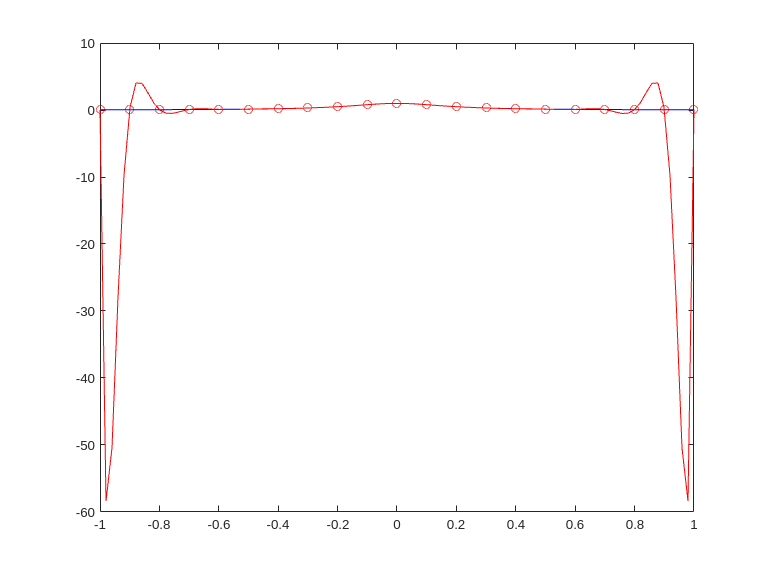

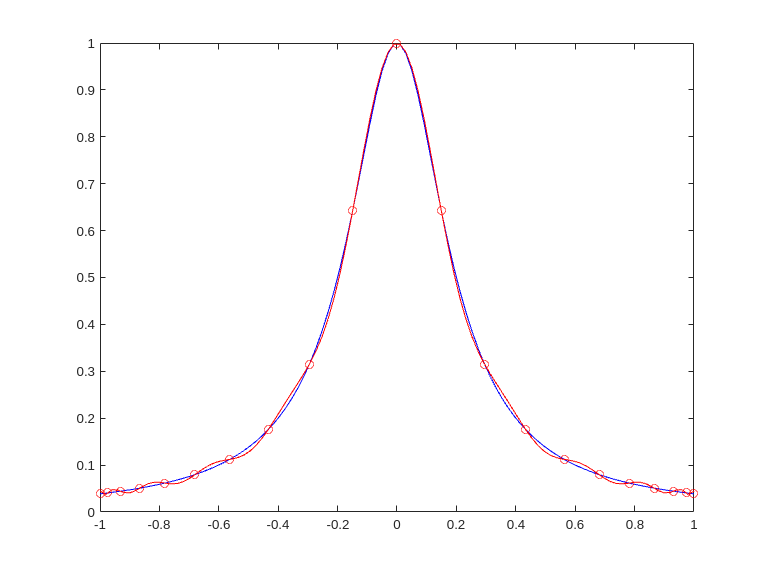

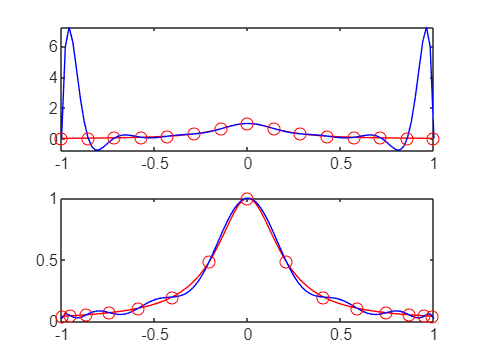

hiba_e = 7.1893

hiba_cs = 0.0461

% Megoldás

% [hiba_e,hiba_cs]=interp_osszehasonlitas(n,f)